    % color_assembly=[color_assembly cell(1, 10-numel(color_assembly))];
    % color_assembly_all= [color_assembly_all ;color_assembly];
total=sum(color_all(1:6));
ALL_color_all=[ALL_color_all ;color_all(1:6)/total];%number of cells among active of each color
ALL_identifier{num_iteration}=identifier;
pathexcel=[PathSave 'ALL_color_brainbow.xls'];
% data =readcell(pathexcel);
% [row , col]=size (data);
% numline=row+1;
writematrix('date',pathexcel,'Range','A1');
writematrix (daytime,pathexcel,'Range',['A' num2str(size(ALL_color_all,1)+1)]);
writematrix('identifier',pathexcel,'Range','B1');
writematrix (identifier,pathexcel,'Range',['B' num2str(size(ALL_color_all,1)+1)]);
writematrix('%red',pathexcel,'Range','C1');
writematrix('%green',pathexcel,'Range','D1');
writematrix('%blue',pathexcel,'Range','E1');
writematrix('%yellow',pathexcel,'Range','F1');
writematrix('%magenta',pathexcel,'Range','G1');
writematrix('%cyan',pathexcel,'Range','H1');

writematrix (color_all(1)/total,pathexcel,'Range',['C' num2str(size(ALL_color_all,1)+1)]);
writematrix (color_all(2)/total,pathexcel,'Range',['D' num2str(size(ALL_color_all,1)+1)]);
writematrix (color_all(3)/total,pathexcel,'Range',['E' num2str(size(ALL_color_all,1)+1)]);
writematrix (color_all(4)/total,pathexcel,'Range',['F' num2str(size(ALL_color_all,1)+1)]);
writematrix (color_all(5)/total,pathexcel,'Range',['G' num2str(size(ALL_color_all,1)+1)]);
writematrix (color_all(6)/total,pathexcel,'Range',['H' num2str(size(ALL_color_all,1)+1)]);
return

num_recording =[6 33 11 20 21 28];%best
% num_recording = [1     2     7    15    18    22    23    24    29    34]%list_444118
% num_recording = [3	25	30	35	36] %list_444119
% num_recording = [ 4	8	9	14	16	26	27	31	32] %444152
% num_recording = [5	10	12	13	17	19	37	38	39	40]  %444175
% num_recording = [6 33]  %411582
% num_recording = [11 20]  %443669
% num_recording = [21 28]  %444112
% %transform into polar coord
% % angles = deg2rad(0:60:300);
% angles = 0:60:300;
% angles = repmat(0:60:300,40,1);
% % [rho, theta] = cart2pol(repmat(angles, size(ALL_color_all, 1), 1), ALL_color_all);
%  figure;polarplot( angles',ALL_color_all','LineWidth',2);
% title('Polar Plot of Animal Measures');
% legend('Animal 1', 'Animal 2', ..., 'Animal 40'); % Add legend for each animal


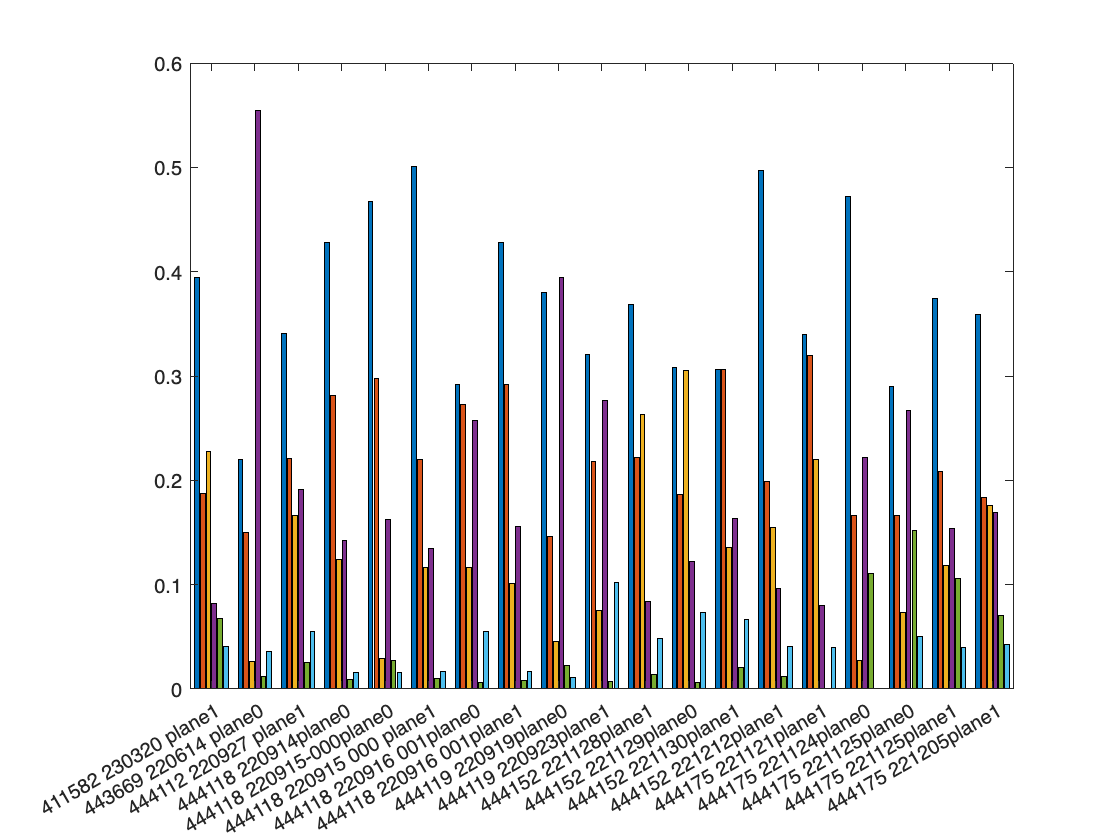

figure;bar(ALL_color_all,'DisplayName','ALL_color_all')
xticks ([1:19])
xticklabels(ALL_identifier);

figure;bar(ALL_color_all(num_recording,:),'DisplayName','ALL_color_all')

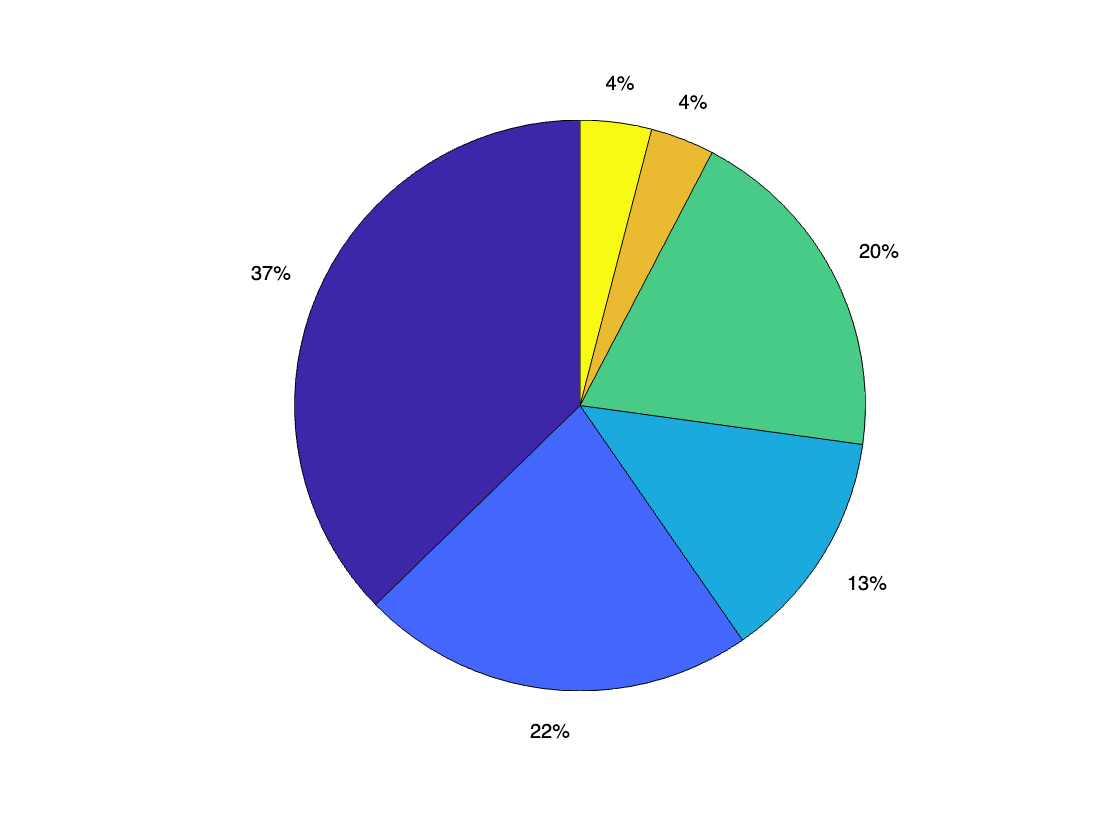

mean_all_color=mean(ALL_color_all,1);
pie(mean(ALL_color_all,1))

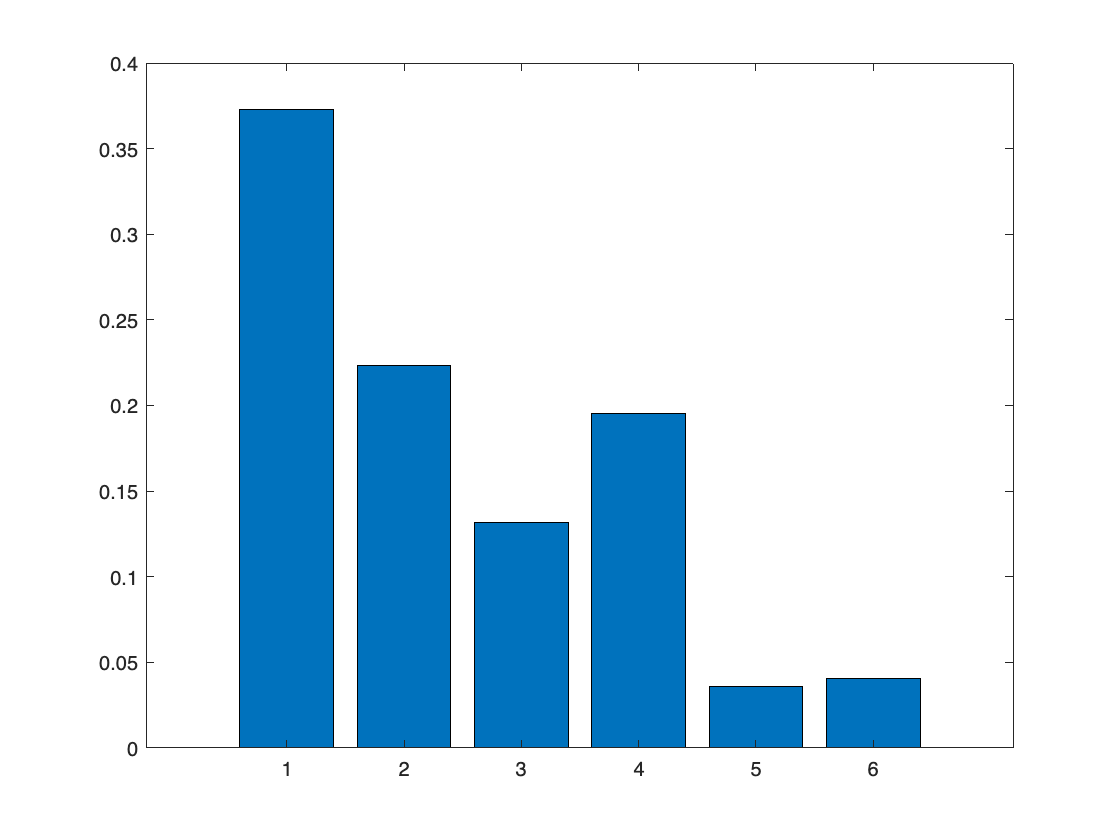

figure;boxplot(ALL_color_all);
bar(mean(ALL_color_all,1))